# DSZOB, cvičenie 2.

## **Zadanie:**

## **Úloha 1 – Základné generovanie signálov**

Vygenerujte a vhodne vizualizujte nasledovné signály (vzorkovacia frekvencia 44.1 kHz, časový úsek 3 sekundy):

- Sínusový signál s frekvenciou zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou = 0,6.

- Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu <0,2:0,5>.

- Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu  <0,1:0,4>.

- Generujte zložený signál ako súčet  z predchádzajúcich vygenerovaných signálov. 

- K zloženému signálu aditívne pripočítajte šum s magnitúdou z rozsahu <0,01:0,05>.

(pomôcka: funkcia *rand()* alebo  *randn() )*

Vygenerované signály si vypočujte po sebe v poradí generovania (zložený signál na záver).

Vygenerované signály vizualizujte!

Pozn.: Môžete sa pokúsit o akord (vid tab. dole)

## **Tab. Temperované ladenie - frekvencie**

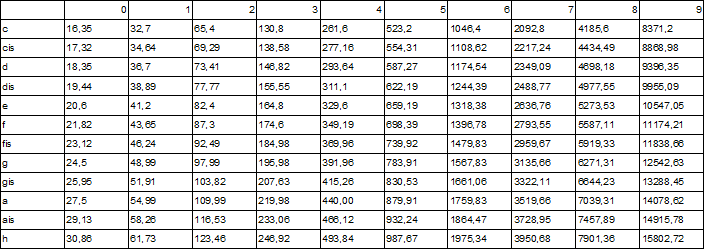

**Príklady akordov / Tóny, z ktorých sa skladá:**

- Cdur / **C, E, G**

- Gdur / **G, H, D**

- Amoll / **A, C, E**

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Riesenie / Solution
f_ais5 = 932.24                                     %vybraný ton č.1

f_ais5 = 932.2400

f_0 = 44.1                                          %vzorkovacia frekvencia pre všetky tóny 1.Úlohy

f_0 = 44.1000

mag_ais5 = 0.6                                      %1. amplitúda

mag_ais5 = 0.6000

x_0 = 0:1/(f_0 * 1000):3                            %vector "časov" kedy sa samplovalo

x_0 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


%1. Sínusový signál s frekvenciou ais 5 a magnitúdou = 0,6:

sinY_ais5 = sin(2*pi*x_0*f_ais5) * mag_ais5         %zdigitalizovaní signál z pôvodného ais 5 tónu.,

sinY_ais5 =          0    0.0795    0.1575    0.2328    0.3040    0.3698    0.4291    0.4809    0.5242    0.5582    0.5824    0.5964    0.5998    0.5927    0.5752    0.5475    0.5101    0.4638    0.4093    0.3476    0.2798    0.2071    0.1307    0.0520   -0.0277   -0.1068   -0.1840   -0.2581   -0.3275   -0.3912   -0.4480   -0.4969   -0.5371   -0.5678   -0.5885   -0.5988   -0.5986   -0.5878   -0.5667   -0.5356   -0.4950   -0.4458   -0.3887   -0.3247   -0.2550   -0.1809   -0.1035   -0.0243    0.0553    0.1339


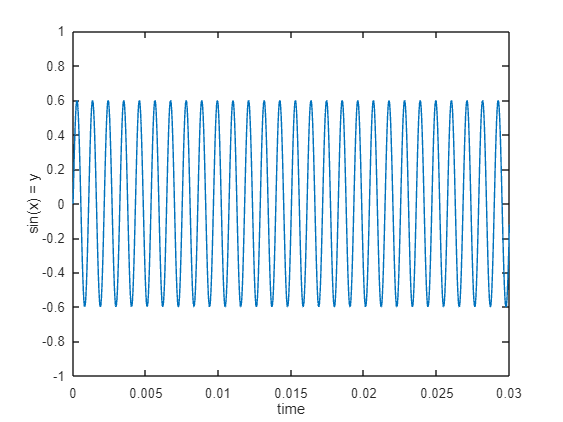

plot(x_0,sinY_ais5)
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.03])                                       %nastavenie grafu, vzhladom na hranice x osi
ylim([-1 1])                                         %nastavenie grafu, vzhladom na hranice y osi

%2. Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu <0,2:0,5>.
f_fis4 = 369.96                                         %vybraný ton č.2

f_fis4 = 369.9600

mag_fis4 = mod(rand() * 2, 0.5)                         %náhodný výber hodnoty amplitúdy, z intervalu 0.2-0.5

mag_fis4 = 0.1294

sinY_fis4 = sin(2 * pi * x_0 * f_fis4) * mag_fis4       %zdigitalizovaní signál z pôvodného fis 4 tónu.

sinY_fis4 =          0    0.0068    0.0136    0.0204    0.0271    0.0337    0.0403    0.0467    0.0530    0.0591    0.0651    0.0709    0.0765    0.0819    0.0871    0.0920    0.0967    0.1011    0.1052    0.1090    0.1126    0.1158    0.1187    0.1212    0.1234    0.1253    0.1269    0.1280    0.1289    0.1293    0.1294    0.1292    0.1286    0.1276    0.1263    0.1246    0.1226    0.1202    0.1175    0.1145    0.1112    0.1075    0.1036    0.0994    0.0949    0.0901    0.0851    0.0798    0.0743    0.0686


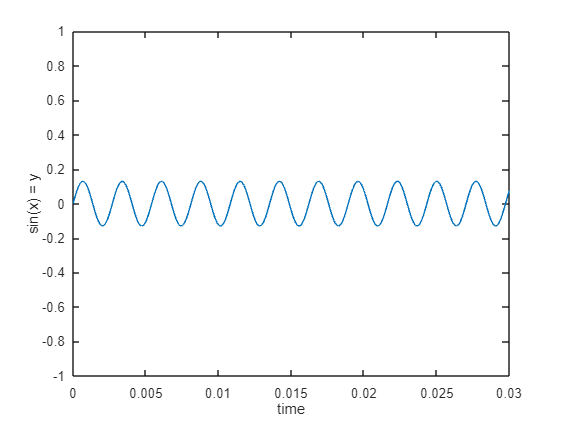

plot(x_0, sinY_fis4)
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.03])
ylim([-1 1])

%3.Sínusový signál s frekvenciou iného zvoleného tónu temperovaného ladenia (vid tab. dole) a magnitúdou z rozsahu  <0,1:0,4>.
f_d2 = 73.41                                            %vybraný ton č.3

f_d2 = 73.4100

mag_d2 = mod(rand() + 0.1, 0.4)                         %náhodný výber hodnoty amplitúdy, z intervalu 0.1-0.4

mag_d2 = 0.2058

sinY_d2 = sin(2 * pi * x_0 * f_d2) * mag_d2             %zdigitalizovaní signál z pôvodného d 2 tónu.

sinY_d2 =          0    0.0022    0.0043    0.0065    0.0086    0.0108    0.0129    0.0151    0.0172    0.0193    0.0215    0.0236    0.0258    0.0279    0.0300    0.0322    0.0343    0.0364    0.0385    0.0406    0.0427    0.0448    0.0469    0.0490    0.0511    0.0532    0.0553    0.0573    0.0594    0.0615    0.0635    0.0656    0.0676    0.0696    0.0716    0.0737    0.0757    0.0777    0.0797    0.0816    0.0836    0.0856    0.0875    0.0895    0.0914    0.0933    0.0952    0.0971    0.0990    0.1009


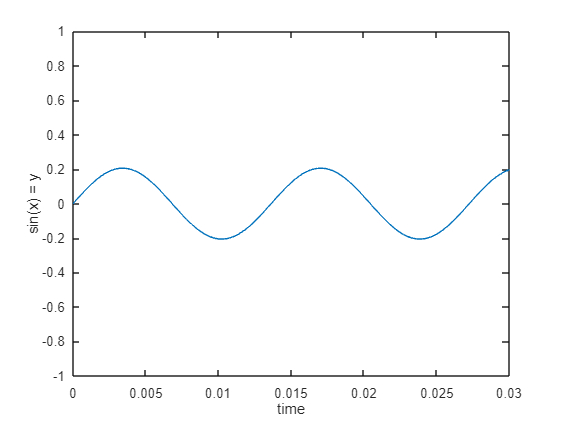

plot(x_0,sinY_d2)
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.03])
ylim([-1 1])

%4.Generujte zložený signál ako súčet  z predchádzajúcich vygenerovaných signálov. 
sumSin = sinY_ais5 + sinY_fis4 + sinY_d2                %výsledny signál po ščítaní dig. signalov podla tónov, asi5, tis4, d2

sumSin =          0    0.0884    0.1754    0.2596    0.3397    0.4143    0.4823    0.5426    0.5943    0.6367    0.6690    0.6909    0.7021    0.7025    0.6923    0.6716    0.6411    0.6013    0.5531    0.4973    0.4351    0.3677    0.2962    0.2222    0.1469    0.0717   -0.0019   -0.0727   -0.1392   -0.2004   -0.2551   -0.3022   -0.3409   -0.3705   -0.3905   -0.4005   -0.4003   -0.3899   -0.3695   -0.3394   -0.3002   -0.2527   -0.1976   -0.1359   -0.0688    0.0025    0.0768    0.1526    0.2286    0.3034


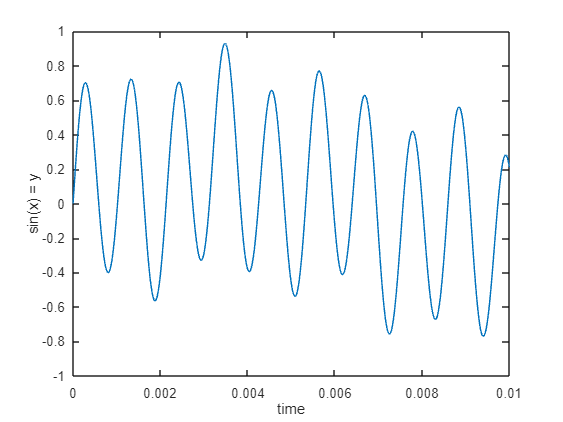

plot(x_0, sumSin)
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.01])
ylim([-1 1])

%5.K zloženému signálu aditívne pripočítajte šum s magnitúdou z rozsahu <0,01:0,05>.
sizeOfSigna = size(sumSin)                      %výpočeť počtu časov vzorkovania

sizeOfSigna =            1      132301


sum = rand(1, sizeOfSigna(2))                   %naplnenie vektora náhodnými čislami, (s ich počtom rovným počtu vzorkovacích časov), keďže sum berieme ako náhodnu a nesuvisiacu hodnotu k hodnote zvuku

sum =     0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547    0.2760    0.6797


sum_mag = mod(rand() + 0.1, 0.5)                %náhodný výber hodnoty amplitúdy, z intervalu 0.1-0.5

sum_mag = 0.1217

sum = sum * sum_mag                             %výsledný signal po pridaní šumu do predošlého súčtu signálov

sum =     0.0155    0.1112    0.0770    0.0119    0.0339    0.0666    0.1165    0.1174    0.0192    0.1181    0.1165    0.0591    0.0974    0.0173    0.0513    0.1115    0.0964    0.1168    0.0798    0.0043    0.1034    0.1137    0.0826    0.0922    0.0904    0.0477    0.0798    0.0208    0.0859    0.0039    0.0337    0.0056    0.0118    0.1002    0.0846    0.0386    0.1157    0.0042    0.0534    0.0464    0.0932    0.0968    0.0227    0.0596    0.0542    0.0787    0.0863    0.0919    0.0336    0.0827


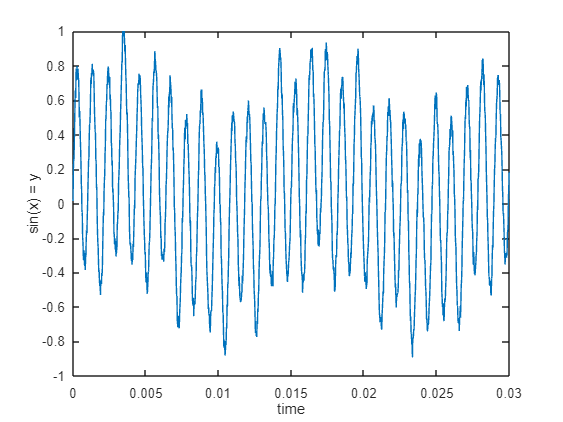

plot(x_0, sumSin + sum)
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.03])
ylim([-1 1])
hold off                                        %vypnutie skladania grafov

% prehravanie signalov, od jednotlivých tónov, po ich sumu, a nakoniec s pridaním sumu
audio1 = audioplayer(sinY_ais5, length(sinY_ais5));
audio2 = audioplayer(sinY_fis4, length(sinY_fis4));
audio3 = audioplayer(sinY_d2, length(sinY_d2));
audio4 = audioplayer(sumSin, length(sumSin));
audio5 = audioplayer(sumSin + sum, length(sum));
playblocking(audio1, 3)
playblocking(audio2, 3)
playblocking(audio3, 3)
playblocking(audio4, 3)
playblocking(audio5, 3)


## **Úloha 2**

Znížte vzorkovaciu frekvenciu u Vami vygenerovaného signálu:

- na polovicu

- na štvrtinu

- na hranicu danú Nyquistovým  teorémom

- a aj s porušením Nyquistovho  teorému. 

Vizualizujte dané signály v jednom grafe. Signál si vypočujte a vyhodnoťte kvalitu.

Pomôcky : funkcia: *downsample()*

%opetovné zadanie niektorých základných premmených pre lepší prehlad (a ovladatelnejsi spustanie, iba sekcie)
fs = 44100;
freq = 932.24;
x_vec = 0:1/fs:3

x_vec =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


%base signal
signal1 = sin(2 * pi * x_vec * freq) * mag_ais5

signal1 =          0    0.0795    0.1575    0.2328    0.3040    0.3698    0.4291    0.4809    0.5242    0.5582    0.5824    0.5964    0.5998    0.5927    0.5752    0.5475    0.5101    0.4638    0.4093    0.3476    0.2798    0.2071    0.1307    0.0520   -0.0277   -0.1068   -0.1840   -0.2581   -0.3275   -0.3912   -0.4480   -0.4969   -0.5371   -0.5678   -0.5885   -0.5988   -0.5986   -0.5878   -0.5667   -0.5356   -0.4950   -0.4458   -0.3887   -0.3247   -0.2550   -0.1809   -0.1035   -0.0243    0.0553    0.1339


% na polovicu
x_1 = downsample(x_vec, 2);
newSin1 = downsample(signal1, 2);
% na štvrtinu
x_2 = downsample(x_1, 2);
newSin2 = downsample(signal1, 4);
 %výpočet potrebného dividera, pre funkciu downsampling, kedže máme
 %základnu hodnotu fs, tak potrebujeme vedieť kolko krát ju mám videliť
 %abych dostal cielovy sampling freq, v tomto prípade pre downsampling
 %signlálu na hranicu nyquistovho teoremu, tj. cca. 2.1x najvyzsia
 %frequencia v signály.
multiOnNyquist = round(fs / (freq * 2.3)) 

multiOnNyquist = 21

%opet výpočet potrebného dividera, ale v tomto prípade pre sample
%frequenciu ktorá je pod hranicou nyquistovho teoremu.
multiDownNyquist = round(fs / (freq * 1.7))

multiDownNyquist = 28

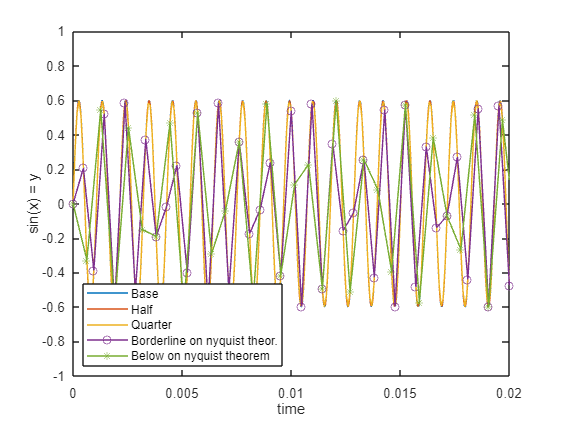


% na hranicu danú Nyquistovým  teorémom
x_3 = downsample(x_vec, multiOnNyquist);
newSin3 = downsample(signal1, multiOnNyquist);
% s porušením nyquistového teorému
x_4 = downsample(x_vec, multiDownNyquist);
newSin4 = downsample(signal1, multiDownNyquist);
plot(x_0, signal1)
% Vizalizácia signálov na jednom grafe
hold on
plot(x_1, newSin1)
plot(x_2, newSin2)
plot(x_3, newSin3, "-o")
plot(x_4, newSin4, "-*")
legend('Base','Half','Quarter','Borderline on nyquist theor.','Below on nyquist theorem','Location','southwest')
xlabel("time")
ylabel("sin(x) = y")
xlim([0 0.02])
ylim([-1 1])
hold off;

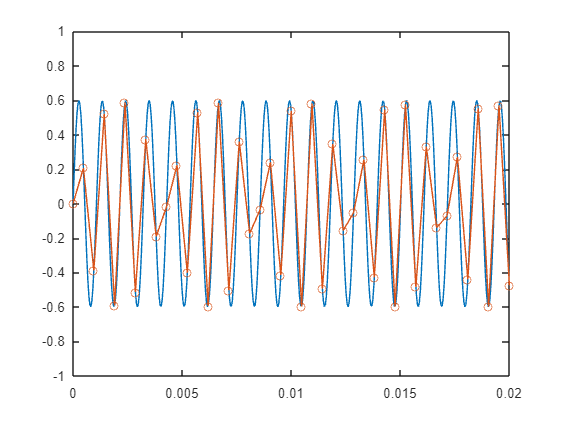

% Vysledok: Grafy ktr. boli podvzorkované na polovicu a stvtinu,
% zachovávaju svoj, priebeh s minimálnou odchylkou od základu, avšak graf
% ktorý bol podvzorkovaný na hranicu nyquist. theoremu. tj. 1/21 pôvodného (vzhladom na to že vzorkovanie má cca. 2x 930 Hz) vykazuje väčšie
% odchylky, ktoré su na hranici podobnosti k pôvodnemu grafu ( výkyvy
% amplitúdi/maximá sú v podobnom umiestnená ako base graf), toto je však už
% porušené u grafu ktr. nedodržiava nyqst. theroem.
plot(x_1, newSin1)
hold on
plot(x_3, newSin3, "-o")
xlim([0 0.02])
ylim([-1 1])
hold off;

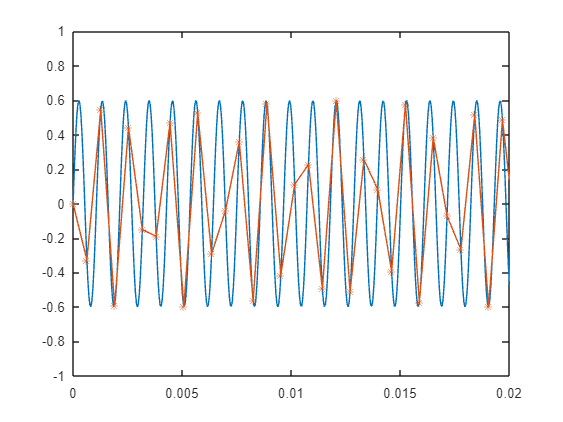

plot(x_1, newSin1)
hold on
plot(x_4, newSin4, "-*")
xlim([0 0.02])
ylim([-1 1])
hold off;

new_audio0 = audioplayer(signal1, length(signal1));
new_audio1 = audioplayer(newSin1, length(newSin1));
new_audio2 = audioplayer(newSin2, length(newSin2));
new_audio3 = audioplayer(newSin3, length(newSin3));
new_audio4 = audioplayer(newSin4, length(newSin4));
playblocking(new_audio0, 3)
playblocking(new_audio1, 3)
playblocking(new_audio2, 3)
playblocking(new_audio3, 3)
playblocking(new_audio4, 3)

% Vzhladom na kvalitu zvuku, tak minimálne prvé tri zvuky, tj. základny
% tón, polovica a štvrtina boli na počutie rovnaké, rozdiel bol
% zaznamenitelný v 4. signále ktr. je na hranici nyquistovho teoremu a v 5.
% boli zmeni zjávne hlavne vzhladom na to že celé úseky zvuku boli zdatelne
% nižšieho tónu
% 